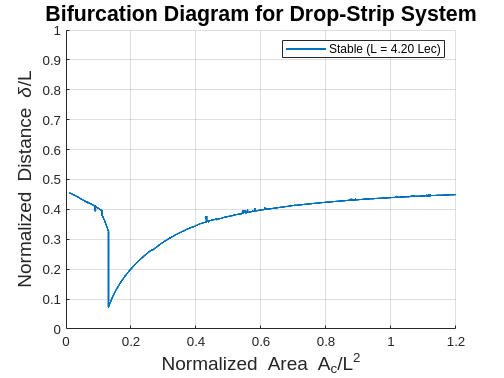

% Parameters

EI = 1;               % Elastic stiffness
gamma = 1;            % Surface tension
w = 1;                % Width of the strip
Lec = sqrt(EI / (gamma * w)); % Elastic-capillary length
L_values = [4.2] * Lec; % Length ratios
num_points = 10000;     % Number of volume points
Ac_norm = linspace(0.01, 1.2, num_points); % Normalized area Ac/L^2
delta_L_stable = zeros(num_points, length(L_values));

% Energy minimization loop
for j = 1:length(L_values)
    L = L_values(j);
    for i = 1:num_points
        % Current normalized area
        Ac = Ac_norm(i) * L^2;

        % Objective function: Total energy
        energy_function = @(x) compute_energy(x, Ac, EI, gamma, w, L);

        % Initial guess for [k, alpha]
        x0 = [0.5, pi/4]; 

        % Minimize the energy function
        options = optimoptions('fminunc', 'Display', 'off', 'Algorithm', 'quasi-newton');
        [x_sol, fval, exitflag] = fminunc(energy_function, x0, options);

        % Extract curvature and compute delta
        k = x_sol(1);
        delta_stable = sin(k * L / 2) / k;
        delta_L_stable(i, j) = delta_stable / L;
    end
end

% Plot bifurcation diagram
figure;
hold on;
colors = ['r', 'b', 'g']; % Colors for each L ratio
for j = 1:length(L_values)
    plot(Ac_norm, delta_L_stable(:, j), '-', 'LineWidth', 1.5, ...
        'MarkerSize', 6, 'DisplayName', sprintf('Stable (L = %.2f Lec)', L_values(j) / Lec));
end

% Add labels, legend, and title
xlabel('Normalized Area A_c/L^2', 'FontSize', 14);
ylabel('Normalized Distance \delta/L', 'FontSize', 14);
title('Bifurcation Diagram for Drop-Strip System', 'FontSize', 16);
ylim([0,1]);
legend show;
grid on;
hold off;

% Energy computation function
function E = compute_energy(x, Ac, EI, gamma, w, L)
    k = x(1); % Curvature
    alpha = x(2); % Angle

    % Capillary area
    Ac_computed = (1 / k^2) * (L * k / 2 - sin(L * k)) / 2 + ...
                  (1 / k^2) * (alpha - sin(2 * alpha) / 2);

    % Elastic energy
    E_el = 0.5 * EI * k^2 * L;

    % Capillary energy
    E_cap = gamma * (2 * alpha * w * sin(L * k / 2) / (k * sin(alpha)) + 2 * Ac_computed);

    % Total energy
    E = E_el + E_cap + 1e6 * (Ac_computed - Ac)^2; % Penalize volume mismatch
end

